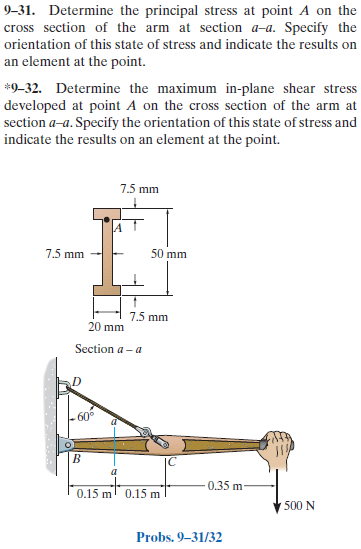

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-31P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-31P-solution-9780136022305) (problem 9-31)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-32P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-32P-solution-9780136022305) (problem 9-32)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

theta = 60*u.deg;
T = sym('T');
Rc(T) = T*cos(theta);

# beam

b = beam;
b = b.add('reaction', 'force', 'Rb', 0);
b = b.add('reaction', 'force', Rc, 0.30*u.m);
b = b.add('concentrated', 'force', -500*u.N, 0.65*u.m);
b.L = 0.65*u.m;

# section properties

yc = [50/2-7.5/2, 0, -50/2+7.5/2]*u.mm;
Ac = [20*7.5, 7.5*(50-2*7.5), 20*7.5]*u.mm^2;
Ic = [20*7.5^3, 7.5*(50-2*7.5)^3, 20*7.5^3]/sym(12)*u.mm^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);
A = sum(Ac);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{22400000000\,x\,\left(10\,x-3\,m\right)\,\left(10\,x+3\,m\right)}{3771\,\text{E}}\,\frac{N}{m^{4}} & \text{ if }x\leq \frac{3}{10}\,m\\ \frac{320000000\,\left(10\,x-3\,m\right)\,\left(200\,x^{2}-330\,x\,m+39\,m^{2}\right)}{1257\,\text{E}}\,\frac{N}{m^{4}} & \text{ if }\frac{3}{10}\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{22400000000\,\left(3\,m^{2}-100\,x^{2}\right)}{1257\,\text{E}}\,\frac{N}{m^{4}} & \text{ if }x\leq \frac{3}{10}\,m\\ \frac{6400000000\,\left(100\,x^{2}-130\,x\,m+23\,m^{2}\right)}{419\,\text{E}}\,\frac{N}{m^{4}} & \text{ if }\frac{3}{10}\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{1750\,x}{3}\,N & \text{ if }x\leq \frac{3}{10}\,m\\ 25\,\left(20\,x-13\,m\right)\,N & \text{ if }\frac{3}{10}\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{1750}{3}\,N & \text{ if }x\leq \frac{3}{10}\,m\\ 500\,N & \text{ if }\frac{3}{10}\,m<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra_vpa = vpa(ra, 6) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Rb} & -583.333\,N\\ T & 2166.67\,N \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

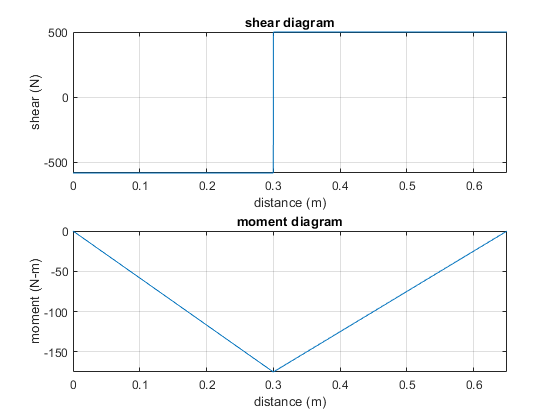

beam.shear_moment(m, v, [0 b.L], {'N' 'm'});

# loads at points A

P = -rs.T*sin(theta);
P_vpa = vpa(P, 6) %#ok<NASGU> 

$$P\_vpa = -1876.39\,N$$

M = m(0.15*u.m);
M_vpa = vpa(M) %#ok<NASGU> 

$$M\_vpa = -87.5\,N\,m$$

V = v(0.15*u.m);
V_vpa = vpa(V, 5) %#ok<NASGU> 

$$V\_vpa = -583.33\,N$$

# stresses at point A

% ------------
% axial stress
% ------------
sigma_axial = rewrite(P/A, u.MPa);
sigma_axial_vpa = vpa(sigma_axial, 3) %#ok<NASGU> 

$$sigma\_axial\_vpa = -3.34\,\mathrm{MPa}$$

% --------------
% bending stress
% --------------
Y = (50-2*7.5)/2*u.mm;
b.I = rewrite(b.I, u.mm);
sigma_bending = rewrite(-M*Y/b.I, u.MPa);
sigma_bending_vpa = vpa(sigma_bending, 3) %#ok<NASGU> 

$$sigma\_bending\_vpa = 9.36\,\mathrm{MPa}$$

% ------------
% shear stress
% ------------
V = v(0.15*u.m);
Q = Qn(1);
t = 7.5*u.mm;
tau_shear = rewrite(-V*Q/(b.I*t), u.MPa);
tau_shear_vpa = vpa(tau_shear, 3) %#ok<NASGU> 

$$tau\_shear\_vpa = 1.51\,\mathrm{MPa}$$

# mohr stresses at point A

sigmax = sigma_axial+sigma_bending;
sigmax_vpa = vpa(sigmax, 3) %#ok<NASGU> 

$$sigmax\_vpa = 6.02\,\mathrm{MPa}$$

sigmay = sym(0)

$$sigmay = 0$$

tauxy = tau_shear;
tauxy_vpa = vpa(tauxy, 3) %#ok<NASGU> 

$$tauxy\_vpa = 1.51\,\mathrm{MPa}$$

[sigmaxp sigmayp tauxyp thetap] = beam.principal(sigmax, sigmay, tauxy);
[sigmaxs sigmays tauxys thetas] = beam.max_shear(sigmax, sigmay, tauxy);

# mohr's circle for point A

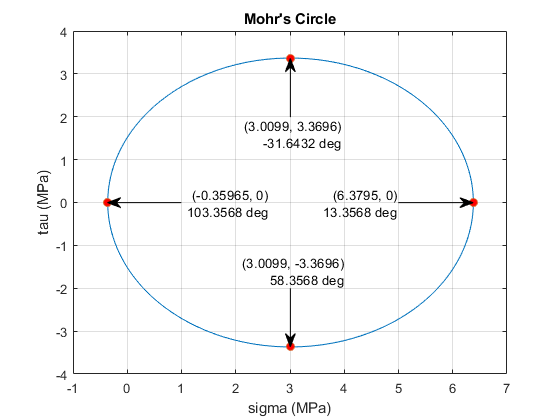

beam.mohr_plot(sigmax, sigmay, tauxy, {'MPa'});
axis([-1 7 -4 4]);
xvals = double(separateUnits([sigmaxp sigmaxs]));
yvals = double(separateUnits([tauxyp tauxys]));
thetavals = double(separateUnits([thetap thetas]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = 5;
      y1 = 0;
    case 2
      x1 = 1;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = 2;
    case 4
      x1 = xvals(4);
      y1 = -2;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear P_vpa M_vpa V_vpa;
clear sigma_axial_vpa sigma_bending_vpa tau_shear_vpa;
clear sigmax_vpa tauxy_vpa;
clear xvals yvals thetavals k x1 y1 x2 y2 text_str;